# **Chapter-2: Mobile Robot Kinematics**

Kinematics is the study of motion without considering the forces that cause it. It describes how position, orientation, velocity, and acceleration change over time. In robotics, kinematics answers a fundamental question: **if we command certain wheel speeds or joint motions, how will the robot move?** It focuses on geometry and motion relationships, not mass, friction, or motor torque.

For mobile robots, kinematics is the foundation of navigation, control, and planning. Before designing controllers or analyzing stability, we must understand how the robot’s structure allows it to move. Without a kinematic model, it is impossible to predict the robot’s trajectory, estimate its pose, or design motion algorithms such as path tracking and obstacle avoidance.

In this chapter, we model the robot chassis as a rigid body moving on a flat, horizontal plane. Consequently, the robot’s configuration can be fully described by three degrees of freedom, its position (x, y) and its orientation $$\theta$$ with respect to a global reference frame. In wheeled robots, each wheel not only contributes to the robot’s overall motion but also imposes constraints on how the robot can move. For instance, a standard wheel allows rolling motion along its plane but restricts lateral (sideways) slipping. When multiple wheels are attached to the same chassis, these individual constraints combine to define the overall motion capabilities of the robot.

## Representing robot pose

The axes $X_I$and $Y_I$ define an arbitrary **inertial frame**, serving as the **global reference frame**. This frame is fixed in the environment and provides a common coordinate system for describing the robot’s motion. To specify the position of the robot, a **reference point** **P** is chosen on the robot’s chassis. The axes {${X_R,Y_R}$} defined at ***P*** form the robot’s **local reference frame**, which translates and rotates with the vehicle. The position of point P in the global reference frame is given by the coordinates $(x, y)$. The **orientation** of the robot, that is the angular difference between the global frame {$X_I$, $Y_I$} and the local frame {${X_R,Y_R}$} is denoted by θ.

Together, these three quantities describe the **pose** of the robot, ${\xi}_I = 

$$\left\lbrack \begin{array}{c}
x\\
y\\
\theta 
\end{array}\right\rbrack$ , The subscript $I$ indicates that the pose is expressed with respect to the **global reference frame**.

Since the local frame changes orientation as the robot moves, this relationship naturally depends on the robot’s current pose. The mapping between these two coordinate systems is accomplished using an **orthogonal rotation matrix**, which accounts for the robot’s instantaneous orientation. The orthogonal rotationmatrix is denoted by $R(\theta )=$ $\left\lbrack \begin{array}{ccc}
\cos \;\theta \; & \sin \;\theta  & 0\\
-\sin \;\theta  & \cos \;\theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$ . Finally the mapping between the **global reference frame and local reference frame (also called robot's frame) **is given by ${\xi}_R = R(\theta){\xi}_I $. Furthermore the mapping is also applicable for mapping of velocities from global reference frame and local reference frame, $\dot{\xi}_R = R(\theta)\dot{\xi}_I $.

# **Forward kinematic models**

The **forward kinematics** of a mobile robot describe how the robot’s **individual wheel motions** produce the **overall motion of the chassis** in the global reference frame. Once the configuration and geometry of the robot are known, the forward kinematic equations determine how the robot’s pose $(x, y, \theta)$ evolves over time.

## Differential-drive forward kinematics

A **differential-drive robot** consists of two independently driven wheels mounted on either side of the chassis (See Fig. 2). Each wheel has a radius $r$. The wheels are separated by a distance $L$, measured between their contact points on the ground. A point $P$ is defined midway between the two wheels and serves as the robot’s **reference point** for position and rotation. 

Let the right and left wheels rotate with angular velocities $\omega_R$ and $\omega_L$, respectively. Given these quantities, the **forward kinematic model** predicts the robot’s instantaneous linear and angular velocities in the **global reference frame**: $\dot{\xi}_I = R(\theta )^T \pmatrix    {v_x \cr 0 \cr \omega}$ . Each wheel contributes both to the **translational** and **rotational** motion of the robot. Since a standard wheel cannot generate lateral motion, the velocity component $v_{y\;}$ in the local frame is always zero. The forward linear velocity of the robot in the local frame is obtained as the average of the tangential velocities of the two drive wheels: $v_x=\frac{r}{2}(\omega_R+\omega_L)$. Furthermore, both wheels are located at a distance $\frac{L}{2}$ from the center point $P$, the **angular velocity** of the robot is given by $\omega =\frac{r}{L}(\omega _R-\omega _L)$. By substitutinh the value of $v_{x\;}$and $\omega$, the forward kinematic model for the differential-drive robot can be given as: $\dot{\xi}_I= \pmatrix {\dot x \cr \dot y \cr \dot \theta} = R(\theta )^T \pmatrix    {\frac{r}{2}(\omega_R+\omega_L) \cr 0 \cr \frac{r}{L}(\omega _R-\omega _L)}$ . This model provides the instantaneous translational and rotational velocities of the robot in the **global reference frame**, given the current wheel speeds and orientation. Once we have the velocity components in the global frame, we can compute how the robot’s **pose evolves over time** by integrating:$x(t) = x_0 + \int_{0}^{t} \dot{x}(\tau)\, d\tau \\
y(t) = y_0 + \int_{0}^{t} \dot{y}(\tau)\, d\tau \\
\theta(t) = \theta_0 + \int_{0}^{t} \dot{\theta}(\tau)\, d\tau$ . 

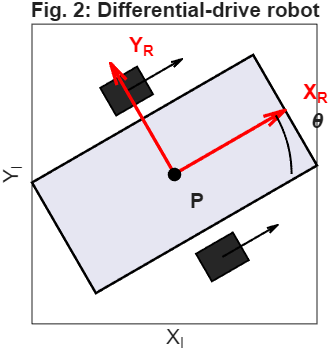

Click on the tab to implement the forward kinematics of a differential-drive mobile robot, using MATLAB to control a robot simulation in CoppeliaSim (e.g., Pioneer P3-DX).

**CoppeliaSim Code Example**

**Environment Setup and Path Configuration:** This block prepares MATLAB to communicate with CoppeliaSim. It finds the simulator location, builds required paths, and ensures all dependencies are available before starting.

 

%% Differential Drive Forward Kinematics (FK) Simulation

% --- 1. SETUP: Dynamic Path Configuration ---
% Get the installation root from the environment variable
coppeliaRoot = getenv('COPPELIA_ROOT');

% Safety check: Ensure the variable exists
if isempty(coppeliaRoot)
    error('Error: COPPELIA_ROOT environment variable not found. Please set it in Windows variables.');
end

% Dynamically build the path to the API and Executable
apiPath = fullfile(coppeliaRoot, 'programming', 'zmqRemoteApi', 'clients', 'matlab');
exePath = fullfile(coppeliaRoot, 'coppeliaSim.exe');

% Add the API path to MATLAB
if exist(apiPath, 'dir')
    addpath(apiPath);
else
    error('API path not found at: %s', apiPath);
end

% --- 2. SETUP: Locate Scene File ---
if matlab.desktop.editor.isEditorAvailable
    % This grabs the full path of the currently open Live Script
    currentScriptPath = fileparts(matlab.desktop.editor.getActiveFilename);
else
    % Fallback: use the current working directory if not running from editor
    currentScriptPath = pwd;
end

% Construct scene path relative to the script location
sceneFile = fullfile(currentScriptPath, 'scenes', 'Terrestial', 'fk.ttt');

% Verify Files Exist
if ~isfile(sceneFile)
    error('Scene file not found! Looked in: %s', sceneFile);
else
    disp(['Scene file found: ', sceneFile]);
end

if ~isfile(exePath)
    error('CoppeliaSim executable not found at: %s', exePath);
end


**Robot Parameters and Simulation Settings**: Defines the physical robot model and experiment settings. This includes wheel size, robot geometry, control inputs, and simulation duration.

% ------------------ ROBOT PARAMETERS ------------------
% Robot physical parameters (set to match model)
r = 0.0975;   % wheel radius (m)
d = 0.330;    % axle length (m)

% commanded wheel speeds (rad/s)
wl_cmd = 0.1;
wr_cmd = 0.3;

% object names in the scene
leftMotorName  = '/leftMotor';
rightMotorName = '/rightMotor';
robotBaseName  = '/PioneerP3DX';

% simulation run time
T_total = 25.0;            % seconds
estimated_scene_dt = 0.05; % used only to size arrays
% ------------------------------------------------------

% --- 3. EXECUTION: Launch and Connect ---

fprintf('Launching CoppeliaSim...\n');
system(['start "" "' exePath '"']);
pause(4.0);  % wait for GUI/process to start

% Connect to RemoteAPIClient (ZMQ)
timeout = 30; % seconds
tic;
client = [];
fprintf('Attempting to connect to API...\n');

while toc < timeout
    try
        client = RemoteAPIClient(); 
        break;
    catch
        pause(0.5);
    end
end

if isempty(client)
    error('Could not create RemoteAPIClient within %d seconds. Check the ZMQ plugin.', timeout);
end

sim = client.getObject('sim');

% --- 4. MAIN SIMULATION LOOP ---
try
    % load scene
    fprintf('Loading scene: %s\n', sceneFile);
    sim.loadScene(sceneFile);
    pause(1.0);

    % get object handles
    leftMotor  = sim.getObject(leftMotorName);
    rightMotor = sim.getObject(rightMotorName);
    robotBase  = sim.getObject(robotBaseName);

    % Start simulation
    fprintf('Starting simulation...\n');
    sim.startSimulation();
    pause(0.05); % small pause to let sim spin up

    % Command the wheel target velocities
    sim.setJointTargetVelocity(leftMotor,  wl_cmd);
    sim.setJointTargetVelocity(rightMotor, wr_cmd);

    % --- Initialize variables ---
    sim_t_prev = sim.getSimulationTime();

    % read initial base pose
    pos0 = sim.getObjectPosition(robotBase, -1); 
    ori0 = sim.getObjectOrientation(robotBase, -1);
    
    % Initialize MATLAB FK variables from sim start
    x = pos0{1}; 
    y = pos0{2}; 
    theta = ori0{3}; 

    % read initial joint positions
    pL_prev = sim.getJointPosition(leftMotor);
    pR_prev = sim.getJointPosition(rightMotor);

    

**Data Logging Setup**: Prepares arrays to store trajectory data from both MATLAB calculations and simulator ground truth for later comparison.

% bookkeeping arrays
    nSteps = ceil(T_total / estimated_scene_dt) + 100; % +100 buffer
    trajectory = zeros(nSteps,3);
    sim_pose   = zeros(nSteps,3);
    sim_time_log = zeros(nSteps,1);

    % optional sign flips if wheel directions differ in model
    wheelSignLeft  = +1;
    wheelSignRight = +1;

    fprintf('Entering main loop (T_total=%.2fs)...\n', T_total);
    k = 0;
    

**Main Simulation Loop (Core Logic)**: This is the heart of the program. It reads sensor data, computes robot motion using forward kinematics, and compares it with simulator results in real time.

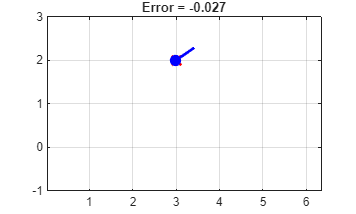

Goal reached


    while true
        % get current simulation time
        sim_t = sim.getSimulationTime();
        dt_sim = sim_t - sim_t_prev;
        
        if dt_sim <= 0
            pause(0.001);
            continue;
        end

        % read current joint positions
        pL_curr = sim.getJointPosition(leftMotor);
        pR_curr = sim.getJointPosition(rightMotor);

        % wrap-correct diffs (handling encoder wrap-around)
        dL = pL_curr - pL_prev;
        if dL > pi,  dL = dL - 2*pi; end
        if dL < -pi, dL = dL + 2*pi; end
        
        dR = pR_curr - pR_prev;
        if dR > pi,  dR = dR - 2*pi; end
        if dR < -pi, dR = dR + 2*pi; end

        % measured angular velocities (rad/s)
        velL = (dL / dt_sim) * wheelSignLeft;
        velR = (dR / dt_sim) * wheelSignRight;

        % --- Forward Kinematics Calculation ---
        v = (r/2) * (velR + velL);
        omega = (r/d) * (velR - velL);

        % integrate pose
        x = x + v * cos(theta) * dt_sim;
        y = y + v * sin(theta) * dt_sim;
        theta = wrapToPi(theta + omega * dt_sim); % Ensure wrapToPi is available or standard func

        % log MATLAB calculation
        k = k + 1;
        if k <= nSteps
            trajectory(k,:) = [x y theta];
        end


        % log Simulator Ground Truth
        pos = sim.getObjectPosition(robotBase, -1); 
        ori = sim.getObjectOrientation(robotBase, -1);
        
        sim_x = pos{1}; 
        sim_y = pos{2}; 
        sim_theta = ori{3};

        if k <= nSteps
            sim_pose(k,:) = [sim_x sim_y sim_theta];
            sim_time_log(k) = sim_t;
        end

        % print status every ~1s of simulated time
        if mod(k, 20) == 0 % approx check to reduce console spam
             fprintf('t=%.2f | MATLAB: (%.2f, %.2f) | Sim: (%.2f, %.2f)\n',...
                sim_t, x, y, sim_x, sim_y);
        end

        % advance previous samples
        pL_prev = pL_curr;
        pR_prev = pR_curr;
        sim_t_prev = sim_t;

        % stop condition
        if sim_t >= T_total
            break;
        end
    end

    % trim logs to actual length
    actualN = min(k, nSteps);
    trajectory = trajectory(1:actualN,:);
    sim_pose   = sim_pose(1:actualN,:);

    % stop motors
    sim.setJointTargetVelocity(leftMotor,  0.0);
    sim.setJointTargetVelocity(rightMotor, 0.0);

    % plot results
    figure('Name','Differential-drive FK: MATLAB vs CoppeliaSim','NumberTitle','off');
    plot(trajectory(:,1), trajectory(:,2), 'LineWidth', 2);
    hold on;
    plot(sim_pose(:,1), sim_pose(:,2), '--', 'LineWidth', 1.5);
    legend('MATLAB FK Prediction', 'CoppeliaSim Ground Truth', 'Location', 'best');
    xlabel('X (m)'); ylabel('Y (m)'); axis equal; grid on;
    title('Forward Kinematics: Predicted vs Simulated');

    % stop sim and quit
    fprintf('Stopping simulation and quitting CoppeliaSim...\n');
    sim.stopSimulation();
    pause(1);
    sim.quitSimulator();
    fprintf('Run complete. Logged %d samples.\n', actualN);

catch ME
    % --- 5. CLEANUP ON ERROR ---
    warning('An error occurred during the simulation:%s%s', newline, ME.message);
    try
        if exist('sim', 'var') && ~isempty(sim)
            sim.stopSimulation();
            sim.quitSimulator();
        end
    catch
        % ignore cleanup errors
    end
    rethrow(ME);
end

% --- Helper Function ---
function ang = wrapToPi(ang)
    ang = mod(ang + pi, 2*pi) - pi;
end

## Try Yourself: PID Heading Control

This example shows how a robot can **use kinematics with feedback control** to reach a target point.

Instead of directly commanding motion, the robot:

- computes the **direction to the goal**

- measures its **heading error**

- uses a **PID controller** to correct its orientation 

## What the Code Does

At each step:

- The robot computes the **vector toward the goal**

- It converts this into a **desired heading angle**

- The difference between desired and current heading gives the **error**

- A **PID controller** computes angular velocity: 

- proportional → reacts to current error 

- integral → accumulates past error 

- derivative → anticipates change 

- The robot updates: 

- its **orientation** using angular velocity 

- its **position** by moving forward 

- The simulation stops once the robot is **close enough to the goal**

##  How to Use This Code

- Run the section to start the animation 

- Tune the controller gains: 

- `Kp` → controls how aggressively the robot turns 

- `Ki` → helps remove steady-state error 

- `Kd` → smooths the motion 

- Re-run after each change to observe the behavior

%% 🎯 Task: PID Heading Control

Kp = 2.0;     % 👉 proportional gain
Ki = 0.05;    % 👉 integral gain
Kd = 0.3;     % 👉 derivative gain

theta = 0;              
pos = [0 0];            
goal = [3 2];           

e_prev = 0;             
e_int = 0;              

dt = 0.1;

figure

for t = 1:200
    
    dir = goal - pos;
    dist = norm(dir);
    
    % --- stop if close to goal ---
    if dist < 0.05
        disp('Goal reached')
        break
    end
    
    target = atan2(dir(2), dir(1));
    
    % --- PID error ---
    err = wrapToPi(target - theta);
    
    e_int = e_int + err*dt;
    e_der = (err - e_prev)/dt;
    
    omega = Kp*err + Ki*e_int + Kd*e_der;
    
    % --- update state ---
    theta = theta + dt*omega;
    pos = pos + 0.05*[cos(theta) sin(theta)];
    
    e_prev = err;
    
    % --- plotting ---
    clf
    plot(goal(1),goal(2),'rx','MarkerSize',10,'LineWidth',2); hold on
    plot(pos(1),pos(2),'bo','MarkerSize',8,'MarkerFaceColor','b')
    quiver(pos(1),pos(2),cos(theta),sin(theta),0.5,'b','LineWidth',2)
    
    xlim([-1 4]); ylim([-1 3])
    axis equal; grid on
    title(['Error = ', num2str(err,2)])
    
    pause(0.05)
end

# **Wheel Kinematics**

The first step in constructing a kinematic model for a mobile robot is to express the **constraints on the motion of its individual wheels**. Just as shown earlier, the motions of all wheels can later be combined to compute the overall motion of the robot chassis. There are five fundamental wheel types, each with distinct kinematic properties:

- Fixed standard wheel

- Steered standard wheel

- Castor wheel

- Swedish (omni) wheel

- Spherical wheel

#### Assumptions

**To keep the analysis tractable, several assumptions are made:**

- The wheel plane always remains vertical.

- Each wheel has a single contact point with the ground.

- There is no slipping at the contact point.

**These assumptions mean that, for each wheel, two constraints must be satisfied:**

- Rolling constraint: motion along the wheel plane must correspond exactly to the wheel’s spin (pure rolling).

- No-slip (lateral) constraint: the wheel must not slide sideways, i.e., motion perpendicular to the wheel plane is zero.

## Fixed Standard Wheel

A **fixed standard wheel** has no steering joint; its orientation relative to the chassis is fixed. It can move only **forward or backward** along the wheel plane and rotate about its ground contact point.

Let:

- $\alpha$ = wheel position angle relative to the robot’s local frame $\left\lbrace X_R ,Y_R \right\rbrace$

- $\beta$ = fixed orientation of the wheel plane relative to the chassis

- $l$ = distance from the wheel’s contact point to the robot reference point PPP

- $r$ = wheel radius

- $\phi \left(t\right)$ = wheel rotation (spin) over time

The motion along the wheel plane can be given by the equation $[sin(\alpha +\beta )-cos(\alpha +\beta )-lcos\beta ]R(\theta )\dot\xi _I-r\dot\phi =0$ **(equation 1) **and the sliding constraint can be given by $[sin(\alpha +\beta )cos(\alpha +\beta )lsin\beta ]R(\theta )\dot\xi _I =0$ **(equation 2)**

Derivation:

The velocity of point $P$ can be given as $v_A=v_P+\omega \times r_{PA}$

For 2D (planar motion), this becomes:


$$v_A=\pmatrix {\dot x R \cr \dot y R}+\dot \theta \pmatrix {-r_{PA,y} \cr r_{PA,x}}$$


For the wheel located at a distance $l$ and angle $\alpha$ : $r_{PA}=\pmatrix {lcos{\alpha} \cr lsin{\alpha}}$

The **rolling direction** of the wheel plane (tangent to its surface) is defined by a unit vector $\pmatrix {cos{\alpha + \beta} \cr sin{\alpha + \beta}}$ and the  **velocity component along this direction** (i.e., rolling motion) is found by projecting $V_A$ into the onto the unit vector: $v_{roll} = \pmatrix {cos{\alpha + \beta} \cr sin{\alpha + \beta}}^TV_A$.

By substituting $V_A$ in the above equation and then algebraically expanding it, we get:


$$v_{roll} = [sin(\alpha +\beta )-cos(\alpha +\beta )-lcos\beta ]R(\theta )\dot \xi I$$


Furthermore, The wheel’s **tangential speed** at the rim due to spinning is: $v_{spin}=r\dot \phi $.

The pure rolling constraints impies: $v_{roll}-v_{spin}=0$.

Or  equivalently, $[sin(\alpha +\beta )-cos(\alpha +\beta )-lcos\beta ]R(\theta )\dot\xi I-r\dot\phi =0$

The first three terms represent the components of robot motion along the direction of the wheel plane. The transformation $𝑅(𝜃)\dot{ 𝜉} _I


	
$ converts global motion parameters to the robot’s local frame so that all variables in the equation are expressed consistently. 

## Steered Standard Wheel

A **steered standard wheel** operates similar to fixed standard wheel, however, it differs only in that it can rotate about a **vertical steering axis**, changing its orientation $ \beta(t) $ over time. Therefore the geometric relations remain the same likethe fixed wheel, but $\beta
$ is now a function of time: $[sin(\alpha +\beta (t) )-cos(\alpha +\beta  (t))(-l)cos\beta (t) ]R(\theta )\dot\xi I-r\dot\phi =0$ **(equation 3) **and the sliding constraint can be given by $[sin(\alpha +\beta(t) )cos(\alpha +\beta(t) )lsin\beta(t) ]R(\theta )\dot\xi _I =0$ **(equation 4)**

## Castor Wheel

A **castor wheel** also steers around a vertical axis, but the steering axis **does not pass through the ground contact point**.  Instead, the contact point $B$ is offset from the vertical axis at point $A$ by a rigid link of length $d$. Let $\beta(t)$ be the steering angle of the wheel, and $\phi(t)$ the spin angle. The rolling constraint is similar to the case of fixed standard wheel because the offset  axis plays no role for motion along the wheel plane: $[sin(\alpha +\beta )-cos(\alpha +\beta )-lcos\beta ]R(\theta )\dot\xi I-r\dot\phi =0$.  However, the **sliding constraint** changes because lateral forces act at the steering axis: $[cos(\alpha +\beta )sin(\alpha +\beta)d + lsin\beta]R(\theta )\dot\xi I-d\dot \beta =0$**. In this equation, any motion orthogonal to the wheel plane must therefore be balanced by a corresponding caster steering rotation.** 

## Swedish Wheel

A **Swedish wheel** (also called an **omni wheel**) adds small rollers around its circumference. These rollers introduce an additional degree of freedom, allowing the wheel to move laterally without slipping.  The angle $\gamma$ between the roller axes and the main wheel plane defines the wheel subtype (e.g., 45° or 90° Swedish wheel). The rolling constraint becomes $[sin(\alpha +\beta +\gamma )-cos(\alpha +\beta +\gamma )-lcos(\beta +\gamma )]R(\theta )\dot\xi _I-r\dot \phi cos\gamma =0$ and the corresponding lateral constraint becomes $[cos(\alpha +\beta +\gamma )sin(\alpha +\beta +\gamma )lsin(\beta +\gamma )]R(\theta ) \dot \xi _I-r  \dot \phi sin\gamma -r  \dot \psi =0$, where $\dot{\psi}$ is the angular speed of the small rollers.

## Spherical Wheel

A **spherical (ball) wheel** has no defined axis of rotation, allowing unrestricted rolling in any direction. It therefore places **no kinematic constraints** on the chassis motion. The roll-rate constraint along the motion direction of the contact point $A$ is given by $[sin(\alpha +\beta )-cos(\alpha +\beta )-lcos\beta ]R(\theta ) \dot \xi I-r \dot \phi =0$ and orthogonal motion is unconstrained:$[cos(\alpha +\beta )sin(\alpha +\beta )lsin\beta ]R(\theta ) \dot \xi _I=0$. 

# **Robot Kinematic Constraints**

Once the kinematic constraints of individual wheel types have been defined, we can derive the overall **kinematic constraints of the robot chassis**. Each wheel explained above restricts certain components of the chassis motion, and therefore the full set of chassis constraints is obtained by combining the individual wheel constraints according to their placement on the robot body. Let us consider a mobile robot with $N_f$ fixed standard wheels and $N_s$ steerable standard wheels with total velocity $V$. Let the **steering angles** of the steerable wheels be denoted by $\beta _s(t)=
\pmatrix{ \beta _{s,1}(t) \cr \beta _{s,2}(t) \cr \vdots  \cr \beta _{s,N_s}(t)}
,$ and the **fixed orientations** of the fixed standard wheels by $\beta _f(t)=
\pmatrix{ \beta _{f,1}(t) \cr \beta _{f,2}(t) \cr \vdots  \cr \beta _{f,N_f}(t)}
$ . Each wheel also has a rotational position about its horizontal axle, we denote these collectively as $\phi (t)=\pmatrix{\phi _f(t) \cr \phi _s(t)}$ , where $\phi _f(t)$ and $\phi_s(t)$ contain the spin angles of fixed and steerable wheels, respectively. The rolling constraints of all wheels can now be combined into one compact matrix denoted by $J(\beta _s)R(\theta ) \dot \xi I-J_r \dot {\phi }(t)=0$ (**equation 5**), where $R(\theta )$ is the $3\times 3$ rotation matrix mapping from the global to the robot’s local reference frame, $J_r$ is a constant diagonal matrix of wheel radii, denoted by $J_r=diag(r_1,r_2,\ldots,r_V)$, and $J(\beta _s)$ aggregates the projections of all wheels onto their respective wheel-plane directions, given by $J(\beta _s)=\pmatrix{J_f \cr J_s(\beta _s)}$ . $J_f$ is an $(N_f \times 3)$ matrix whose rows contain the three coefficients from **equation 1 **for each fixed standard wheel. $J_s(\beta _s)$ is an $(N_s \times 3)$ matrix whose rows contain the corresponding terms from **equation 3 **for each steerable standard wheel**. **Thus** equation 5 **represents the **rolling constraints for all standard wheels simultaneously.**

Similarly, we can assemble the sliding constraints for all standard wheels, which is given by $C(\beta _s)R(\theta ) \dot \xi _I=0$ (**equation 6**), where $C(\beta _s)= \pmatrix{C_f \cr C_s(\beta _s)}$ , $C_f$ is an $(N_f \times 3)$ matrix whose rows contain the coefficients from **equation 2** and $C_s(\beta _s)$ is an $(N_s \times 3)$ matrix whose rows contain the corresponding terms from **equation 4 **for each steerable standard wheel.

# **Mobile Robot Maneuverability**

## Mobility

The mobility of the overall robot is its ability to directly move in the environment while satisfying all the individual sliding constraints of the wheels. The combined sliding constraints for all standard wheels can be separated into fixed wheel constraint denoted by $C_fR(\theta )\dot\xi _I=0$ and steerable wheel constraint denoted by $C_s(\beta _s)R(\theta )\dot\xi _I=0$. For both constraints to hold, the instantaneous chassis motion $R(\theta )\dot\xi _I$ must lie in the **null space** of the combined projection matrix $C(\beta _s)$. In other words, admissible instantaneous motions are those vectors $V$ satisfying $
C(\beta _s)V=0$. We can therefore define the **degree of mobility** mmm as the dimension of the null space of $C(\beta _s)$, given by $m=dim\mathcal{N}(C(\beta _s))=3-rank(C(\beta s))$.

Interpretation of the value of ***m***:

- m=3: robot is fully mobile (no independent standard-wheel sliding constraints — e.g., only omni/spherical/castor wheels).

- m=2: two degrees of instantaneous freedom (common for differential-drive and many tricycle configurations).

- m=1: only one instantaneous degree of freedom (e.g., a bicycle geometry with one fixed and one steerable standard wheel).

- m=0: completely constrained (degenerate; no planar motion possible).

## Steerability

Steerability captures the number of independently controllable steering parameters. The **degree of steerability** $s$ is the rank of the steerable-wheel constraint matrix: $s=rank(C_s(\beta _s))$.

## Maneuverability

The overall **degree of maneuverability** $M
$of the robot is the sum of mobility and steerability $M=m+s.$ Its is the total number of degrees of freedom the robot can manipulate either directly via wheel speeds or indirectly via steering.


$$\[
\begin{array}{|c|c|c|c|}
\hline
\textbf{Configuration} &
\textbf{Degree of Mobility } (m) &
\textbf{Degree of Steerability } (s) &
\textbf{Degree of Maneuverability } (M = m + s) \\[4pt]
\hline
\textbf{Omnidirectional} &
3 &
0 &
3 \\[6pt]
\hline
\textbf{Differential Drive} &
2 &
0 &
2 \\[6pt]
\hline
\textbf{Tricycle} &

1 &
1 &
2 \\[6pt]
\hline
\textbf{Two-Steer (Dual Steer)} &

1 &
2 &
3 \\[6pt]
\hline
\end{array}
\]
$$


# **Mobile Robot Workspace**

The **maneuverability** of a robot defines how many independent control inputs (wheel speeds and steering angles) the robot can use to influence its motion. However, a robot also operates in a physical **environment**, which determines the possible *positions and orientations* it can reach, this larger space is called its **workspace**.

For example, an **Ackerman (car-like) vehicle** has two control degrees of freedom:

- one for steering,

- and one for driving the wheels.

Yet, on a flat plane, the vehicle’s *pose* can be described by **three parameters**: its position $(x,y)$ and orientation $ \theta$. So although the car has only two control inputs $(M=2)$, it can eventually reach any $(x, y, \theta)$, its **workspace has 3 degrees of freedom** (DOF = 3). This shows that a robot’s workspace DOF can exceed its *instantaneous* maneuverability. Next, we formalize this distinction. To define the workspace, it is helpful to first consider the **admissible velocity space** of the robot.

Given the robot’s kinematic constraints, its velocity space describes the independent velocity components it can command at any instant.

This number of independent velocity components is called the **Differential Degrees of Freedom (DDOF) ,**${DDOF} = \text{number of independently achievable velocities at an instant.}$. By definition, the DDOF of a robot is **equal to its degree of mobility** ($m$),$\text{DDOF} = m$.

## Workspace Degrees of Freedom

A robot’s **workspace DOF** represents the number of pose parameters needed to describe its configuration in the environment. For a planar robot, $\text{Workspace DOF} = 3 \quad \text{(i.e., }x, y, \theta\text{).}$ It is worth noting that the number of controllable instantaneous velocities (DDOF) is never greater than the total number of pose variables (DOF), $DDOF \le  M \le  DOF$. 

## Holonomic Robots

The term **holonomic** describes systems whose motion constraints can be expressed purely as functions of position (not velocities).

In mobile robotics, this concept distinguishes **holonomic** and **nonholonomic** robots.

- A **holonomic constraint** can be written only in terms of position variables (e.g., $ x, y, \theta$).

- A **nonholonomic constraint** involves **velocity terms** (derivatives) and **cannot** be integrated to a position-only form.

Furthermore, a robot is **holonomic** if and only if: $\text{DDOF} = \text{DOF}$.

- Nonholonomic robots have fewer instantaneous DOFs than their workspace allows (e.g., car-like robots).

- Holonomic robots can instantaneously move in all directions of their workspace.

# **Kinematic of Quacopter**

A quadcopter is a flying robot that moves in three-dimensional space. Unlike wheeled robots, it is not constrained to a plane. Its motion is therefore described using **six degrees of freedom (6-DOF)**:

- Position: $\left(x,y,z\right)$

- Orientation: $(\phi, \theta, \psi)$ (roll, pitch, yaw) 

- The full state of the quadcopter is: $\left\lbrack x\;y\;z\;\phi \;\theta \;\psi {\left.\right\rbrack }^T \right.$

This extends the planar pose representation used earlier for mobile robots. The pose of a quadcopter in 3D space is defined by its position and orientation with respect to a global reference frame. Similar to planar robots, this transformation can be represented using a homogeneous transformation matrix. 

Let the position of the quadcopter be $p= \pmatrix {x \cr y \cr z}
$. The rotation from body frame to inertial frame is given by: 

$R = \pmatrix{ 
 \cos\psi \cos\theta & \cos\psi \sin\theta s\phi - \sin\psi \cos\phi & \cos\psi \sin\theta \cos\phi + \sin\psi \sin\phi \cr 

\sin\psi \cos\theta & \sin\psi \sin\theta \sin\phi + \cos\psi \cos\phi & \sin\psi \sin\theta \cos\phi - \cos\psi \sin\phi \cr 

- \sin\theta & \cos\theta \sin\phi & \cos\theta \cos\phi 
 }

$.

The complete transformation is: $T= \pmatrix {R & p \cr 0 & 1}
$.

**MATLAB Code Example**

**Environment Setup and Quadcopter Parameters:** This block prepares the simulation environment and defines the physical structure of the quadcopter. It sets how the drone is shaped, how fast the simulation runs, and how motors are arranged in space.

%% ---------------- Kinematics of Quadcopter ----------------
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
close all; clc;

%================ QUADCOPTER PARAMETERS =================
L = 0.3;           
dt = 0.05;         

% Motor positions (X configuration)
bodyFrame = [ L, -L, -L,  L;
             -L, -L,  L,  L;
              0,  0,  0,  0];


**Forward Kinematics (Attitude Motion)**: This part shows how changing roll, pitch, and yaw affects the orientation of the quadcopter. The drone stays in one place but rotates in 3D space.

%% ========================================================================
%  SCENARIO 1: FORWARD KINEMATICS (ATTITUDE CONTROL)
%==========================================================================
disp('Scenario 1: Attitude Kinematics');

T_fk = 10;
time = 0:dt:T_fk;

f1 = figure('Name','Quadcopter Attitude Control', ...
            'Color','w', ...
            'WindowStyle','normal', ...
            'Position',[100 100 700 600]);
set(f1,'Visible','on');

axis equal; grid on; hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Forward Kinematics: Roll–Pitch–Yaw');
view(3);
xlim([-1 1]); ylim([-1 1]); zlim([0 1.5]);

% Graphics objects
h_Arms = plot3([0 0],[0 0],[0 0],'k','LineWidth',3);
h_M1 = scatter3(0,0,0,120,'r','filled');
h_M2 = scatter3(0,0,0,120,'g','filled');
h_M3 = scatter3(0,0,0,120,'b','filled');
h_M4 = scatter3(0,0,0,120,'y','filled');
h_Body = plot3(0,0,0,'ko','MarkerFaceColor','k','MarkerSize',8);
h_Thrust = quiver3(0,0,0,0,0,1,0.4,'m','LineWidth',2);

z_hover = 0.6;

**Attitude Motion Update (Core FK Logic)**: Generates time-varying roll, pitch, and yaw angles and applies rotation to the quadcopter body. This shows how orientation affects the motor positions in space.

for k = 1:length(time)

    if ~ishandle(f1), break; end

    t = time(k);

    roll  = deg2rad(20)*sin(2*t);
    pitch = deg2rad(20)*cos(2*t);
    yaw   = deg2rad(30)*sin(0.5*t);

    pos = [0;0;z_hover];
    R = getQuadRotationMatrix(roll,pitch,yaw);
    motors = R*bodyFrame + pos;

    

 **Visualization Update (Rendering Attitude)**: Updates the graphical model in real time, including thrust direction.

set(h_Arms,'XData',[motors(1,1) motors(1,3) NaN motors(1,2) motors(1,4)],...
               'YData',[motors(2,1) motors(2,3) NaN motors(2,2) motors(2,4)],...
               'ZData',[motors(3,1) motors(3,3) NaN motors(3,2) motors(3,4)]);

    set(h_M1,'XData',motors(1,1),'YData',motors(2,1),'ZData',motors(3,1));
    set(h_M2,'XData',motors(1,2),'YData',motors(2,2),'ZData',motors(3,2));
    set(h_M3,'XData',motors(1,3),'YData',motors(2,3),'ZData',motors(3,3));
    set(h_M4,'XData',motors(1,4),'YData',motors(2,4),'ZData',motors(3,4));

    set(h_Body,'XData',pos(1),'YData',pos(2),'ZData',pos(3));

    z_axis = R(:,3);
    set(h_Thrust,'XData',pos(1),'YData',pos(2),'ZData',pos(3),...
                 'UData',z_axis(1),'VData',z_axis(2),'WData',z_axis(3));

    title(sprintf('Roll %.1f° | Pitch %.1f° | Yaw %.1f°',...
        rad2deg(roll),rad2deg(pitch),rad2deg(yaw)));

    drawnow limitrate;
end


**Inverse Kinematics (Trajectory Tracking)**: Now the problem is reversed. Instead of giving angles, we give a desired trajectory and compute the required roll, pitch, and yaw to follow that path.

%% ========================================================================
%  SCENARIO 2: INVERSE KINEMATICS (TRAJECTORY TRACKING)
%==========================================================================
disp('Scenario 2: Inverse Kinematics');
pause(1);

T_ik = 20;
time = 0:dt:T_ik;

f2 = figure('Name','Quadcopter Trajectory Tracking', ...
            'Color','w', ...
            'WindowStyle','normal', ...
            'Position',[850 100 700 600]);
set(f2,'Visible','on');

axis equal; grid on; hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Inverse Kinematics: Banking into the Turn');
view(3);

h_Path = animatedline('Color','b','LineStyle','--','LineWidth',1.5);
h_Arms2 = plot3([0 0],[0 0],[0 0],'k','LineWidth',2);

h_M1 = scatter3(0,0,0,80,'r','filled');
h_M2 = scatter3(0,0,0,80,'g','filled');
h_M3 = scatter3(0,0,0,80,'b','filled');
h_M4 = scatter3(0,0,0,80,'y','filled');

h_Thrust2 = quiver3(0,0,0,0,0,1,0.4,'m','LineWidth',2);

g = 9.81;

**Desired Trajectory and Motion Derivatives**: Defines a 3D path and computes velocity and acceleration. These are used to determine how the quadcopter must tilt to follow the path.

for k = 1:length(time)

    if ~ishandle(f2), break; end

    t = time(k);

    xd = 3*sin(0.5*t);
    yd = 3*sin(t);
    zd = 1 + 0.5*sin(0.2*t);

    vx = 1.5*cos(0.5*t);
    vy = 3*cos(t);

    ax = -0.75*sin(0.5*t);
    ay = -3*sin(t);

**Inverse Kinematics (Compute Orientation**): Converts desired motion into required roll, pitch, and yaw. This is how a quadcopter “banks” to move.

    pitch = -ax/g;
    roll  =  ay/g;
    yaw   = atan2(vy,vx);

    pos = [xd;yd;zd];
    R = getQuadRotationMatrix(roll,pitch,yaw);
    motors = R*bodyFrame + pos;

    addpoints(h_Path,xd,yd,zd);

    set(h_Arms2,'XData',[motors(1,1) motors(1,3) NaN motors(1,2) motors(1,4)],...
                'YData',[motors(2,1) motors(2,3) NaN motors(2,2) motors(2,4)],...
                'ZData',[motors(3,1) motors(3,3) NaN motors(3,2) motors(3,4)]);

    set(h_M1,'XData',motors(1,1),'YData',motors(2,1),'ZData',motors(3,1));
    set(h_M2,'XData',motors(1,2),'YData',motors(2,2),'ZData',motors(3,2));
    set(h_M3,'XData',motors(1,3),'YData',motors(2,3),'ZData',motors(3,3));
    set(h_M4,'XData',motors(1,4),'YData',motors(2,4),'ZData',motors(3,4));

    z_axis = R(:,3);
    set(h_Thrust2,'XData',pos(1),'YData',pos(2),'ZData',pos(3),...
                  'UData',z_axis(1),'VData',z_axis(2),'WData',z_axis(3));

    xlim([xd-3 xd+3]); ylim([yd-3 yd+3]); zlim([0 4]);

    drawnow limitrate;
end

disp('Simulation Complete');


**Rotation Matrix Function**: Defines how roll, pitch, and yaw combine to produce a full 3D rotation. This is the mathematical backbone of quadcopter kinematics.

%% ========================================================================
% ROTATION MATRIX (ZYX)
%==========================================================================
function R = getQuadRotationMatrix(roll,pitch,yaw)
Rz = [cos(yaw) -sin(yaw) 0;
      sin(yaw)  cos(yaw) 0;
      0         0        1];

Ry = [cos(pitch) 0 sin(pitch);
      0          1 0;
     -sin(pitch) 0 cos(pitch)];

Rx = [1 0 0;
      0 cos(roll) -sin(roll);
      0 sin(roll)  cos(roll)];

R = Rz * Ry * Rx;
end


# Kinematics of Walking Robots

The kinematic model of a walking robot describes the relationship between the joint variables of a leg, $\mathbf{q} = (q_1, \ldots, q_n)^T,
$ and the position and orientation of the foot, $\mathbf{x} = (x, y, z, r, p, y)^T,
$ where $\left(r,p,y\right)$ denote roll, pitch, and yaw, respectively, and for rotary joints, the joint variable is the relative angle between two consecutive links. For prismatic (sliding) joints, the joint variable is the link extension. As in any open-loop articulated kinematic chain, the kinematic model can be divided into forward kinematics and inverse kinematics. Forward kinematics determines the foot pose $\left(x,y,z,r,p,y\right)$ from the joint variables $\mathbf{q}.$ Inverse Kinematics determines the joint variables $\mathbf{q}$ required to achieve a desired foot pose.

## Forward Kinematics: The Denavit–Hartenberg (D–H) Convention

Consider a leg with n degrees of freedom. Then:

- The leg contains n joints.

- The leg consists of n+1 links, indexed from 0 (hip) to n (foot).

- Joint $i$ connects link $i-1$ to link $i$.

- Each joint has a joint variable $q_i.$

- A reference frame $i$ is rigidly attached to each link.

- Frame 0, at the hip, is the inertial reference frame.

Because frame $i$ moves rigidly with link $i$, the coordinates of any point $p_i$ fixed on link $i$ are constant in frame $i$. If link $i
$ rotates relative to link $i-1$, the point coordinates in frame $i-1$ become $p_{i-1}= {}^{i-1}R_i\, p_i
$. Here,${}^{i-1}R_i
$ is the rotation matrix mapping coordinates from frame $i$ to frame $i-1$, assuming the two frame origins coincide. 

In the general case of rotation and translation is given by $p_{i-1}= {}^{i-1}R_i\, p_i + {}^{i-1}d_i$, which can be written in homogeneous coordinates as $\pmatrix{ p_{i-1} \cr 1 } = \pmatrix{ {}^{i-1}R_i & {}^{i-1}d_i \cr 0 & 1 } \pmatrix{ p_i\cr 1} $. The matrix ${}^{i-1}A_i= \pmatrix{ {}^{i-1}R_i & {}^{i-1}d_i\cr 0 & 1 }$ is called the homogeneous transformation matrix. It maps coordinates from frame $i$ into frame $i-1$.  In its standard form, the homogeneous transformation for joint $i$ is given by ${}^{i-1}A_i= \pmatrix{ \cos\theta_i & -\cos\alpha_i\sin\theta_i & \sin\alpha_i\sin\theta_i & a_i\cos\theta_i

\cr 
\sin\theta_i & \cos\alpha_i\cos\theta_i & -\sin\alpha_i\cos\theta_i & a_i\sin\theta_i

\cr

0 & \sin\alpha_i & \cos\alpha_i & d_i

\cr

0 & 0 & 0 & 1 }$, here $a_i ,\alpha_i$ are geometric link parameters (constants), $\theta_{i\;}$is the rotary joint angle$d_i$ prismatic displacement. The total forward kinematic model, i.e the transformation from the foot frame n to the hip frame 0 is given by ${}^{0}A_n = {}^{0}A_1 \, {}^{1}A_2 \cdots {}^{n-1}A_n$.

# Inverse Kinematics:

The inverse kinematics problem consists of determining the joint variables $\mathbf{q} = (q_1,\ldots,q_n)^T$ required to achieve a desired foot position and orientation. For a leg with 3 degrees of freedom, the forward kinematics can be expressed as $\pmatrix{ a_{11} & a_{12} & a_{13} & x\cr a_{21} & a_{22} & a_{23} & y\cr a_{31} & a_{32} & a_{33} & z\cr 0 & 0 & 0 & 1 } =

 {}^{0}\!A_{1}(q_1)\, {}^{1}\!A_{2}(q_2)\, {}^{2}\!A_{3}(q_3)$, here $(x,y,z)^T$ is the foot position, the columns $(a_{11},a_{21},a_{31})^T,\; (a_{12},a_{22},a_{32})^T,\; (a_{13},a_{23},a_{33})^T$ represent the orientation vectors of the foot frame expressed in the hip frame. This equation orresponds to a set of 12 nonlinear equations in 3 unknowns. Solving this system directly is difficult, and even when a unique forward kinematic mapping exists, the inverse problem may:

- have **no solution** (kinematic constraints not satisfied),

- have **one solution**, or

- have **multiple valid solutions** (e.g., elbow-up vs elbow-down configurations).

This nonlinearity is typical for open-loop articulated mechanisms.

Several general techniques exist for solving inverse kinematics of open-chain mechanisms:

- **Geometric methods: **Based on trigonometric relations, vector geometry, and spatial reasoning.

- **Algebraic methods: **Based on eliminating variables from the kinematic equations to obtain polynomial equations in the unknown joint variables.

- **Inverse transform techniques: **Based on manipulating the forward kinematic matrices directly to isolate joint variables.

**Environment Setup and Robot Parameters**: This block prepares the simulation and defines the physical structure of the biped robot. It sets leg lengths, hip height, and timing, which together determine how the robot will move and appear.

**MATLAB Code Example**

**Environment Setup and Robot Parameters**: This block prepares the simulation and defines the physical structure of the biped robot. It sets leg lengths, hip height, and timing, which together determine how the robot will move and appear.

%% ---------------- BIPED WALKING ROBOT ----------------
com.mathworks.services.Prefs.setBooleanPref('LiveEditorFigureVisible', false);
close all; clc;

%% ---------------- ROBOT PARAMETERS ----------------
L1 = 0.5;
L2 = 0.5;
HipH = 0.95;

dt = 0.05;


**Forward Kinematics (Leg Swing)**: Demonstrates how joint angles alone determine the shape of each leg. The robot does not move forward; instead, both legs swing in place to show how angles control position.

%% ========================================================================
% SCENARIO 1: FORWARD KINEMATICS (LEG SWING)
%==========================================================================
disp('Scenario 1: Forward Kinematics');

T_fk = 5;
time = 0:dt:T_fk;

f1 = figure('Color','w','Name','Biped FK');
set(f1,'Visible','on');

ax1 = axes('Parent',f1);
axis(ax1,'equal'); grid(ax1,'on'); hold(ax1,'on');
axis(ax1,[-1 1 -1.2 0.5]);
xlabel('X'); ylabel('Y');
title('Forward Kinematics: Swinging Legs');

h_LegL = plot(ax1,[0 0 0],[0 0 0],'b-o','LineWidth',3,'MarkerFaceColor','b');
h_LegR = plot(ax1,[0 0 0],[0 0 0],'r-o','LineWidth',3,'MarkerFaceColor','r');

plot(ax1,[-0.2 0.2],[0 0],'k-','LineWidth',5);

for k = 1:length(time)

 
if ~ishandle(f1), break; end
t = time(k);


**Leg Motion Generation + FK Computation**: Generates periodic joint angles (like walking rhythms) and uses forward kinematics to compute where each joint and foot is located.

q1_L = deg2rad(30)*sin(3*t);
q2_L = deg2rad(20)*sin(3*t + pi/2);

q1_R = deg2rad(30)*sin(3*t + pi);
q2_R = deg2rad(20)*sin(3*t + pi + pi/2);

[p0_L, p1_L, p2_L] = solveLegFK_DH(q1_L,q2_L,L1,L2);
[p0_R, p1_R, p2_R] = solveLegFK_DH(q1_R,q2_R,L1,L2);

set(h_LegL,'XData',[p0_L(1) p1_L(1) p2_L(1)],...
           'YData',[p0_L(2) p1_L(2) p2_L(2)]);

set(h_LegR,'XData',[p0_R(1) p1_R(1) p2_R(1)],...
           'YData',[p0_R(2) p1_R(2) p2_R(2)]);

drawnow;
pause(0.02);
 

end


**Walking (Inverse Kinematics):** Now the robot actually walks forward. Instead of giving joint angles, we define where the feet should go and compute the required angles to achieve that motion.

%% ========================================================================
% SCENARIO 2: WALKING (INVERSE KINEMATICS)
%==========================================================================
disp('Scenario 2: Walking');
pause(1);

stepLen = 0.5;
vel     = 0.4;

T_total = 15;
time = 0:dt:T_total;

f2 = figure('Color','w','Name','Biped Walking');
set(f2,'Visible','on');

ax2 = axes('Parent',f2);
axis(ax2,'equal'); grid(ax2,'on'); hold(ax2,'on');
xlabel('X'); ylabel('Y');
title('Inverse Kinematics: Walking');

plot(ax2,[-2 10],[0 0],'k-');

h_WalkL = plot(ax2,[0 0 0],[0 0 0],'b-o','LineWidth',3,'MarkerFaceColor','b');
h_WalkR = plot(ax2,[0 0 0],[0 0 0],'r-o','LineWidth',3,'MarkerFaceColor','r');
h_Torso = plot(ax2,[0 0],[0 0.4],'k-','LineWidth',4);

axis(ax2,[-1 4 -0.5 2]);

for k = 1:length(time)

 
if ~ishandle(f2), break; end
t = time(k);


**Gait Planning (Hip and Foot Trajectory)**: Defines how the robot moves forward and how each foot follows a walking pattern with stance and swing phases.

% Hip motion
x_hip = vel*t;
y_hip = HipH;

% Gait timing
cycleTime = stepLen/vel*2;

[x_foot_L,y_foot_L] = getFootTrajectory(t,cycleTime,stepLen,vel);
[x_foot_R,y_foot_R] = getFootTrajectory(t+cycleTime/2,cycleTime,stepLen,vel);


**Inverse Kinematics (Core Walking Logic)**: Converts desired foot positions into joint angles. This is the key step that allows the robot to walk.

% Inverse kinematics
dx_L = x_foot_L - x_hip;
dy_L = y_foot_L - y_hip;

dx_R = x_foot_R - x_hip;
dy_R = y_foot_R - y_hip;

[q1_L,q2_L] = solveLegIK(dx_L,dy_L,L1,L2);
[q1_R,q2_R] = solveLegIK(dx_R,dy_R,L1,L2);

% Forward kinematics for drawing
[~,p1_L,p2_L] = solveLegFK_DH(q1_L,q2_L,L1,L2);
[~,p1_R,p2_R] = solveLegFK_DH(q1_R,q2_R,L1,L2);

% Update left leg
set(h_WalkL,'XData',[x_hip x_hip+p1_L(1) x_hip+p2_L(1)],...
            'YData',[y_hip y_hip+p1_L(2) y_hip+p2_L(2)]);

% Update right leg
set(h_WalkR,'XData',[x_hip x_hip+p1_R(1) x_hip+p2_R(1)],...
            'YData',[y_hip y_hip+p1_R(2) y_hip+p2_R(2)]);

% Torso
set(h_Torso,'XData',[x_hip x_hip],...
             'YData',[y_hip y_hip+0.4]);

% Camera follow
xlim(ax2,[x_hip-1.5 x_hip+2.5]);

drawnow;
pause(0.02);
 

end

disp('Simulation Complete');


**Helper Functions (Core Math Engine)**: These functions implement the mathematical backbone of the robot: forward kinematics, inverse kinematics, transformations, and gait generation.

%% ================= HELPER FUNCTIONS =================

function [p0, p1, p2] = solveLegFK_DH(q1, q2, L1, L2)

T01 = getDHMatrix(0, L1, 0, q1 - pi/2);
T12 = getDHMatrix(0, L2, 0, q2);

T02 = T01 * T12;

p0 = [0; 0; 0];
p1 = T01(1:3, 4);
p2 = T02(1:3, 4);

end

function T = getDHMatrix(alpha, a, d, theta)

c = cos(theta); s = sin(theta);
ca = cos(alpha); sa = sin(alpha);

T = [c -s*ca s*sa a*c;
s  c*ca -c*sa a*s;
0  sa    ca    d;
0  0     0     1];

end

function [q1, q2] = solveLegIK(x, y, L1, L2)

r = sqrt(x^2 + y^2);

if r > (L1 + L2)*0.999
r = (L1 + L2)*0.999;
end

c2 = (r^2 - L1^2 - L2^2) / (2*L1*L2);
q2 = acos(c2);

alpha = asin((L2 * sin(q2)) / r);
q1 = atan2(y, x) - alpha;
q1 = q1 + pi/2;

end

function [x, y] = getFootTrajectory(t, cycleTime, stepLen, vel)

phi = mod(t, cycleTime) / cycleTime;
stepIndex = floor(t / cycleTime);
stepStartPos = stepIndex * (stepLen * 2);

if phi < 0.5
x = stepStartPos;
y = 0;
else
swingPhi = (phi - 0.5) * 2;
x = stepStartPos + (stepLen * 2) * swingPhi;
y = 0.2 * sin(swingPhi * pi);
end

end


## Try Yourself: Foot Placement Control (DH + Gait)

This example shows how a legged robot can move by **controlling where its foot should go**, instead of directly controlling joint angles.

The robot uses:

- a **desired foot location (task space)**

- **inverse kinematics (IK)** to compute joint angles 

- **DH-based forward kinematics** to draw the leg 

- a simple **gait cycle** to move the foot smoothly 

## What the Code Does

At each step:

- A **target foot position** is defined by: `x_target, y_target`

- A **gait cycle** generates intermediate foot motion: 

- **Stance phase** → foot moves along the ground 

- **Swing phase** → foot lifts and moves to the target 

- The current foot position $(x_f, y_f)$ is sent to **inverse kinematics**, which computes: 

- `theta1` → hip angle 

- `theta2` → knee angle 

- These angles are used in **DH transformations** to compute: 

- joint positions 

- final foot position 

- The leg is then drawn using: 

- links (thigh + shank) 

- joints (hip + knee) 

- foot (end-effector) 

## How to Use This Code

- Run the section to start the animation 

- Change the target foot location: 

- `x_target` → forward/backward placement 

- `y_target` → height or ground contact 

- Re-run the section after each change


% --- USER INPUT (tune foot location) ---
x_target = 0.3;    
y_target = -0.5;   

% --- DH PARAMETERS (structure) ---
a1 = 0.5;   
a2 = 0.4;



% --- DH transform ---
dh = @(a,theta) [cos(theta) -sin(theta) 0 a*cos(theta);
                 sin(theta)  cos(theta) 0 a*sin(theta);
                 0           0          1 0;
                 0           0          0 1];

figure

for t = 1:200
    
    % --- phase ---
    phase = mod(t/40,1);
    
    % --- gait trajectory toward target ---
    if phase < 0.5
        % STANCE: move along ground toward target
        alpha = phase*2;
        xf = (1-alpha)*(-0.2) + alpha*x_target;
        yf = -0.6;
    else
        % SWING: lift and place at target
        s = (phase-0.5)*2;
        xf = x_target;
        yf = -0.6 + (y_target + 0.6)*sin(pi*s);
    end
    
    % --- IK (from foot position) ---
    D = (xf^2 + yf^2 - a1^2 - a2^2)/(2*a1*a2);
    D = max(min(D,1),-1);
    
    theta2 = atan2(sqrt(1-D^2), D);
    theta1 = atan2(yf,xf) - atan2(a2*sin(theta2), a1 + a2*cos(theta2));
    
    % --- FK using DH (for visualization) ---
    T1 = dh(a1, theta1);
    T2 = dh(a2, theta2);
    T  = T1*T2;
    
    p0 = [0;0];
    p1 = T1(1:2,4);
    p2 = T(1:2,4);
    
    clf; hold on
    
    % --- links ---
    plot([p0(1) p1(1)], [p0(2) p1(2)], ...
        'LineWidth',4,'Color',[0 0.4 1])
    plot([p1(1) p2(1)], [p1(2) p2(2)], ...
        'LineWidth',4,'Color',[1 0.4 0])
    
    % --- joints ---
    plot(p0(1),p0(2),'ko','MarkerFaceColor','k','MarkerSize',8)
    plot(p1(1),p1(2),'ko','MarkerFaceColor','k','MarkerSize',8)
    
    % --- foot ---
    plot([p2(1)-0.08 p2(1)+0.08],[p2(2) p2(2)],'k','LineWidth',3)
    
    % --- target ---
    plot(x_target, y_target,'rx','LineWidth',2)
    
    % --- current desired trajectory point ---
    plot(xf, yf,'go')
    
    % --- ground ---
    plot([-1 1],[-0.6 -0.6],'k--')
    
    axis equal; grid on
    xlim([-1 1]); ylim([-1 0.8])
    
    title(['Target: (',num2str(x_target,2),', ',num2str(y_target,2),')'])
    
    pause(0.05)
end


# **Quiz**

1) A differential-drive robot has wheels of radius $$r = 0.1\text{ m}$$. The wheels are rotating at the same speed, $$\dot{\phi}_1 = \dot{\phi}_2 = 5\text{ rad/s}$$. According to the forward kinematic model, what is the forward linear velocity $$v$$ of the robot?

"0.5 m/s"
switch ans
    case "0.5 m/s"
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

2) Consider a differential-drive robot where the distance between the two wheels is $$L = 0.5\text{ m}$$ (so the distance from the center $$P$$ to a wheel is $$l = 0.25\text{ m}$$). If the wheel radius is $$r = 0.1\text{ m}$$, the right wheel rotates at $$\dot{\phi}_1 = 6\text{ rad/s}$$, and the left wheel rotates at $$\dot{\phi}_2 = 2\text{ rad/s}$$, what is the angular velocity $\omega$ of the robot?

"0.8 m/s"
switch ans
    case "0.8 m/s"
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

3) For a robot chassis, the degree of mobility $$m$$  is defined mathematically as:

"The dimension of the null space of the fixed-wheel sliding constraint matrix."
switch ans
    case "The dimension of the null space of the fixed-wheel sliding constraint matrix."
        disp("Right Answer");
  
        
    otherwise
        disp("Wrong Answer.");
end

# **Exercise**

- Connect MATLAB to CoppeliaSim and drag four-legged robot from the model browser window.

- Retrieve the world coordinates (x, y) of all four foot-tip contacts using sim.getObjectPosition.

- Retrieve the world coordinates of the robot's Chassis Center of Mass (CoM).

- Using MATLAB figures, plot the **Support Polygon** formed by the four feet.

- Select one leg to "lift" (e.g., Front-Right). Before moving the robot, conceptually remove this point from your MATLAB plot.

-  Does the current CoM fall inside the new triangle formed by the remaining three legs?

- **Execution:** Send a command to the robot to lift the chosen leg (retract the tibia/foot).

- Observe the simulation. Does the robot tip over? Compare the physical result with your prediction.

-  Calculate the **Centroid** of the 3-legged support triangle (the safe zone).

- Calculate the vector difference between the current CoM and the target Centroid.

**Deliverable:** Generate a MATLAB plot showing:

- The original 4-point support polygon.

- The unstable 3-point triangle (with original CoM marked 'X').

- **Insight:** Explain the relationship between the *Stability Margin* and the distance of the CoM from the edge of the support polygon.